# Quantitative Methods for Finance

2025 Marina Dolfin

# QMF1_7_Data_Analysys

## Addressing the problem of overfitting

**(A short theoretical background is provided at the end of the Live Script.)**

Show, on a controlled toy problem, why in-sample $R^2$ is a poor criterion for model selection: as model complexity grows, training $R^2$ increases even when the model is fitting noise (this is a teaching toy example using synthetic data to illustrate overfitting, the limits of$R^2$ and the general concept of cross-validation).

Workflow:

- Generate data from a given function and add some noise (in this way I'm perfectly aware of the best fitting!)

- **Fit polynomials** of increasing degree d∈{1,2,4,8,16}

- Compute the $R^2$ 

- **Visualize:** scatter data + fitted curves; plot **degree vs metrics**

- Apply cross-validation

- **Visualize:** scatter data + fitted curves; plot **degree vs metrics** (train $R^2$ ↑ monotone; test/CV error ↓ then ↑).

- Observing the impact of overfitting in a simple example

I choose a polynomial function of order 2 (a parabola)


$$y = ax^2+bx+c$$


I add an unbiased gaussian noise (zero mean) and a quite large standard deviation

$y = ax^2+bx+c + \epsilon$       with     $\epsilon\sim N(0,\sigma)$

Fit polynomials of degree 1, 2, 4, 8, and 16 with polyfit/polyval

Compute in-sample $R^2$ for each fit and plot all curves against the data

Read the legend to see training $R^2$ rise with degree while the shape becomes unstable (overfitting)

Why this matters

Training $R^2$ is monotone non-decreasing with added regressors, so it rewards complexity, not generalization.

High-degree models can interpolate noise and look impressive in-sample but perform poorly out-of-sample.

Good practice: validate with a hold-out/test set or k-fold cross-validation, and consider penalties for complexity (adjusted R squared, AIC/BIC) and predictive metrics (RMSE/MAE).

In order to **use fitting to make predictions,** we need **in-sample and out-sample cross-validation** to avoid for instance the problem of overfitting (too many degrees of freedom in the model).

Eventually, I explore the impact of overfitting again using a toy model.

First, I need to generate the variable x over a given domain

x = -10 : 11;


then I set the vector of coefficients of the polynomial

c = [3 0 0];


then I evaluate the polynomial

sigma = 35;  %variance of the gaussian noise

data = polyval(c,x) + sigma*randn(1,length(x));


and fit with polynomials of order 1, 2,4,8,16, respectively

fitorder1coeff = polyfit(x,data,1);  %get the coefficient of the fitting

fitorder1 = polyval(fitorder1coeff,x); %get the polynomial



fitorder2coeff = polyfit(x,data,2);  %get the coefficient of the fitting

fitorder2 = polyval(fitorder2coeff,x); %get the polynomial


fitorder4coeff = polyfit(x,data,4);  %get the coefficient of the fitting

fitorder4 = polyval(fitorder4coeff,x); %get the polynomial



fitorder8coeff = polyfit(x,data,8);  %get the coefficient of the fitting

fitorder8 = polyval(fitorder8coeff,x); %get the polynomial


fitorder16coeff = polyfit(x,data,16);  %get the coefficient of the fitting


fitorder16 = polyval(fitorder16coeff,x); %get the polynomial



mean_data = mean(data); 

Rsquared_fit1 = 1-(sum((data-fitorder1).^2))/(sum((data-mean_data).^2))

Rsquared_fit1 = 0.0402


Rsquared_fit2 = 1-(sum((data-fitorder2).^2))/(sum((data-mean_data).^2))

Rsquared_fit2 = 0.9199



Rsquared_fit4 = 1-(sum((data-fitorder4).^2))/(sum((data-mean_data).^2))

Rsquared_fit4 = 0.9309



Rsquared_fit8 = 1-(sum((data-fitorder8).^2))/(sum((data-mean_data).^2))

Rsquared_fit8 = 0.9639



Rsquared_fit16 = 1-(sum((data-fitorder16).^2))/(sum((data-mean_data).^2))

Rsquared_fit16 = 0.9721

plot the data and the fit

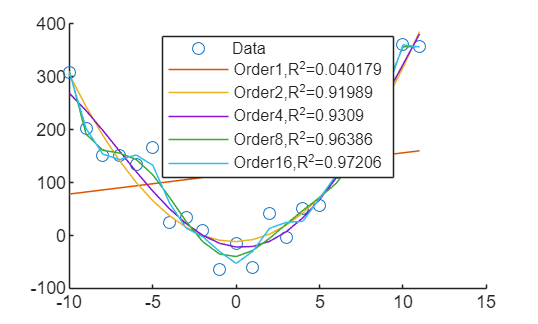

%ylim([-1 400])

scatter(x,data)


hold on

plot(x,fitorder1,x,fitorder2,x,fitorder4,x,fitorder8,x,fitorder16)

legend('Data',...
    strcat('Order1,R^2=', num2str(Rsquared_fit1)),...
 strcat('Order2,R^2=', num2str(Rsquared_fit2)),...
    strcat('Order4,R^2=', num2str(Rsquared_fit4)),...
 strcat('Order8,R^2=', num2str(Rsquared_fit8)),...   
 strcat('Order16,R^2=', num2str(Rsquared_fit16)),...
'Location',"north")

hold off

This is an example of something that often happens in statistics. The misuse of fitting data to statistical sample. It is called **overfitting**.

I added too many degrees of freedom in my model, and I just started fitting not only the underlying process but start fitting also the noise.

By fitting only to a training set, I can get something that look as a great fit, but in reality it is a too complex model. The only way to detect this is to make cross-validation. By cross-validation I can guess whether I did a good job or I get overfitting.

# Cross-validation

To see how well my model works I need to see how well it predict new data.

Because of the fact that condition on Rsquared is necessary but not sufficient.

I need to train my models on a set of data and then test them on another set of data.

I can either use models on the dataset1 to predict point of the  dataset 2 or viceversa.

Let's go to apply model 2 to dataset 2

I will generate two sets of data from the parabola  function, again by adding some noise

dataTrain = polyval(c,x) + sigma*randn(1,length(x));

dataTest = polyval(c,x) + sigma*randn(1,length(x));


The two sets will be slightly different due to the randomness of the added data.

Now take the two datasets and fit models

and fit with polynomials of order 2,4,8,16, respectively.

Fit the first set of data (training set)

fitorder2coeffTrain = polyfit(x,dataTrain,2);  %get the coefficient of the fitting

fitorder2Train = polyval(fitorder2coeffTrain,x); %get the polynomial


fitorder4coeffTrain = polyfit(x,dataTrain,4);  %get the coefficient of the fitting

fitorder4Train = polyval(fitorder4coeffTrain,x); %get the polynomial



fitorder8coeffTrain = polyfit(x,dataTrain,8);  %get the coefficient of the fitting

fitorder8Train = polyval(fitorder8coeffTrain,x); %get the polynomial


fitorder16coeffTrain = polyfit(x,dataTrain,16);  %get the coefficient of the fitting


fitorder16Train = polyval(fitorder16coeffTrain,x); %get the polynomial


Evaluate the goodness of fit using the R squared


mean_train = mean(dataTrain); 

Rsquared_fit2Train = 1-(sum((dataTrain-fitorder2Train).^2))/(sum((dataTrain-mean_train).^2));


Rsquared_fit4Train = 1-(sum((dataTrain-fitorder4Train).^2))/(sum((dataTrain-mean_train).^2));


Rsquared_fit8Train = 1-(sum((dataTrain-fitorder8Train).^2))/(sum((dataTrain-mean_train).^2));


Rsquared_fit16Train = 1-(sum((dataTrain-fitorder16Train).^2))/(sum((dataTrain-mean_train).^2));




plot the data and the fit

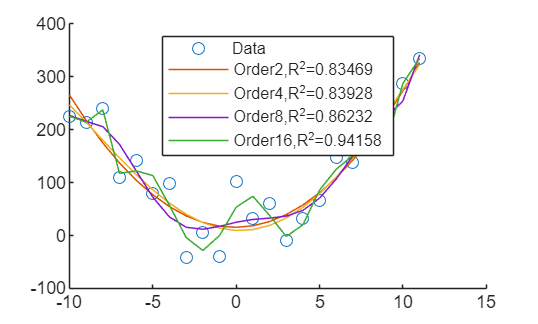

%ylim([-1 400])

scatter(x,dataTrain)


hold on

plot(x,fitorder2Train,x,fitorder4Train,x,fitorder8Train,x,fitorder16Train)

legend('Data',...
    strcat('Order2,R^2=', num2str(Rsquared_fit2Train)),...
    strcat('Order4,R^2=', num2str(Rsquared_fit4Train)),...
 strcat('Order8,R^2=', num2str(Rsquared_fit8Train)),...   
 strcat('Order16,R^2=', num2str(Rsquared_fit16Train)),...
'Location',"north")

hold off

and the second set of data (test data)

fitorder2coeffTest = polyfit(x,dataTest,2);  %get the coefficient of the fitting

fitorder2Test = polyval(fitorder2coeffTest,x); %get the polynomial


fitorder4coeffTest = polyfit(x,dataTest,4);  %get the coefficient of the fitting

fitorder4Test = polyval(fitorder4coeffTest,x); %get the polynomial



fitorder8coeffTest = polyfit(x,dataTest,8);  %get the coefficient of the fitting

fitorder8Test = polyval(fitorder8coeffTest,x); %get the polynomial


fitorder16coeffTest = polyfit(x,dataTest,16);  %get the coefficient of the fitting


fitorder16Test = polyval(fitorder16coeffTest,x); %get the polynomial


Evaluate the goodness of fit using the R squared


mean_test = mean(dataTest); 

Rsquared_fit2Test = 1-(sum((dataTest-fitorder2Test).^2))/(sum((dataTest-mean_test).^2));


Rsquared_fit4Test = 1-(sum((dataTest-fitorder4Test).^2))/(sum((dataTest-mean_test).^2));


Rsquared_fit8Test = 1-(sum((dataTest-fitorder8Test).^2))/(sum((dataTest-mean_test).^2));


Rsquared_fit16Test = 1-(sum((dataTest-fitorder16Test).^2))/(sum((dataTest-mean_test).^2));




plot the data and the fit

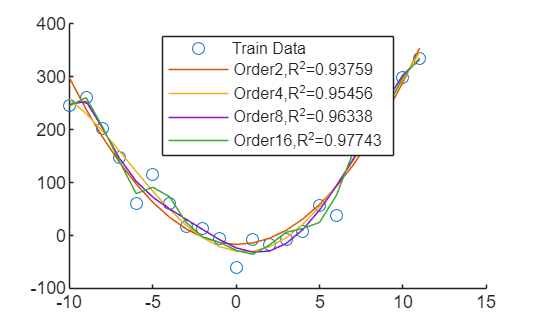

%ylim([-1 400])

scatter(x,dataTest)


hold on

plot(x,fitorder2Test,x,fitorder4Test,x,fitorder8Test,x,fitorder16Test)

legend('Train Data',...
    strcat('Order2,R^2=', num2str(Rsquared_fit2Test)),...
    strcat('Order4,R^2=', num2str(Rsquared_fit4Test)),...
 strcat('Order8,R^2=', num2str(Rsquared_fit8Test)),...   
 strcat('Order16,R^2=', num2str(Rsquared_fit16Test)),...
'Location',"north")

hold off

Evaluate the goodness of fit using the R squared


mean_test = mean(dataTest); 

Rsquared_fit2Test_new = 1-(sum((dataTest-fitorder2Train).^2))/(sum((dataTest-mean_train).^2));


Rsquared_fit4Test_new = 1-(sum((dataTest-fitorder4Train).^2))/(sum((dataTest-mean_train).^2));


Rsquared_fit8Test_new = 1-(sum((dataTest-fitorder8Train).^2))/(sum((dataTest-mean_train).^2));


Rsquared_fit16Test_new = 1-(sum((dataTest-fitorder16Train).^2))/(sum((dataTest-mean_train).^2));




plot the data and the fit

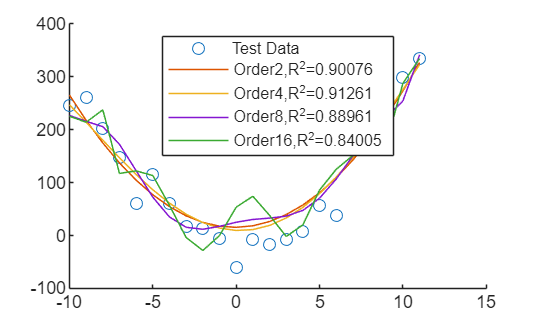

%ylim([-1 400])

scatter(x,dataTest)


hold on

plot(x,fitorder2Train,x,fitorder4Train,x,fitorder8Train,x,fitorder16Train)

legend('Test Data',...
    strcat('Order2,R^2=', num2str(Rsquared_fit2Test_new)),...
    strcat('Order4,R^2=', num2str(Rsquared_fit4Test_new)),...
 strcat('Order8,R^2=', num2str(Rsquared_fit8Test_new)),...   
 strcat('Order16,R^2=', num2str(Rsquared_fit16Test_new)),...
'Location',"north")

hold off

**The rule is: try on one set and test on another.**

**This is cross-validation.**

Summarizing, one can observef from the last two graphics that in the first I get the fitting models from a set of data and then I tested them on a slightly different set of data coming from the same process. 

What I observe is that there are some models that more or less do the same job on the train and on the test data, whilst for instance the 16 degrees model on the test set behaves much more bad then in the training set. In fact the coefficient of determinations drops significantly when I try to fit new data.

So, increasing the degrees of freedom above some value I can get a worse model.

So we can detect that something is going bad when our coefficient of determination is dropping down when we try to fit to noew data our model that was going very well of the training set of data.

# Exploring the effects of overfitting

If the data are perfect and we are adding unuseful degrees of freedom, the fitting will tell us simply to ignore that variable, just by getting 0 for the related coefficient. But if the data are noisy, what the model is starting to do is actually fitting the noise and what is giving a better R squared value  is not a better fit.

The point to focus on is that when the model is too complex (overfitted) there is no backside effect when data are perfect; on the contrary it may make wong prediction when data are noisy.

Let's consider a very simple set of data

x = [0 1 2 3];

y = x;


These data are clearly on a straight line. What happens if we try ti fit however a parabola?

%fit1 = fitlm(x,y,'quadratic')

fit1_coeff = polyfit(x,y,2) %get the coefficients

fit1_coeff =      0     1     0



fit1 = polyval(fit1_coeff,x)% get the polynomial

fit1 =      0     1     2     3


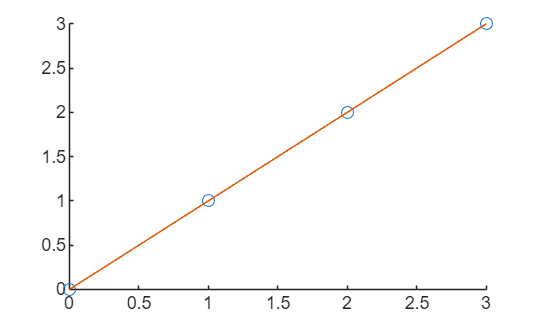


scatter(x,y)

hold on

plot(x,fit1)

hold off

Clearly the fittiging recognizes that the coefficient of the quadratic term is zero and ignores it.

In fact, if we plot the fitting we simply get a straight line

Also if we add a value


x = [0 1 2 3 20];

y = x;

fit1 = polyval(fit1_coeff,x)% get the polynomial

fit1 =      0     1     2     3    20


the fitting will behave good

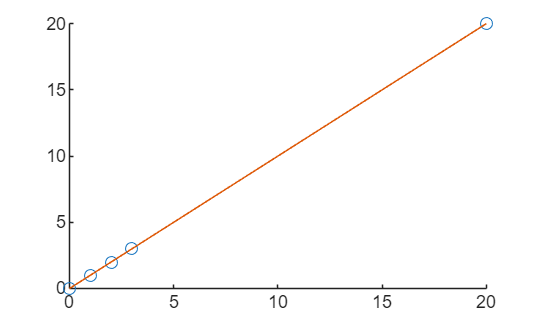



scatter(x,y)

hold on

plot(x,fit1)

hold off

What happens if we add a bit of noise in the data?

x_noisy = [0 1 2 3 ];
y_noisy =[0 1 2 3.1 ];




Now we perform again the quadratic fitting on the noisy data


fit2_coeff = polyfit(x_noisy,y_noisy,2) %get the coefficients

fit2_coeff =     0.0250    0.9550    0.0050



fit2 = polyval(fit2_coeff,x_noisy)% get the polynomial

fit2 =     0.0050    0.9850    2.0150    3.0950


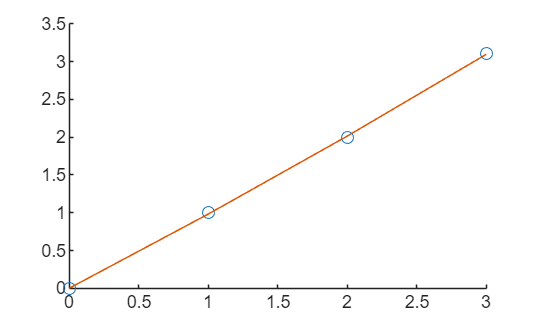


scatter(x_noisy,y_noisy)

hold on

plot(x_noisy,fit2)

hold off

The fitting looks now slightly different. But the big difference is observed if we use new data

xnoisy =  [0 1 2 3 20];

ynoisy = [0 1 2 3.1 20];



fit2 = polyval(fit2_coeff,xnoisy)% get the polynomial

fit2 =     0.0050    0.9850    2.0150    3.0950   29.1050


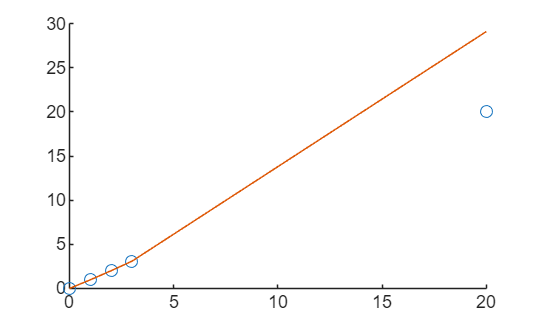




scatter(xnoisy,ynoisy)

hold on

plot(xnoisy,fit2)

hold off

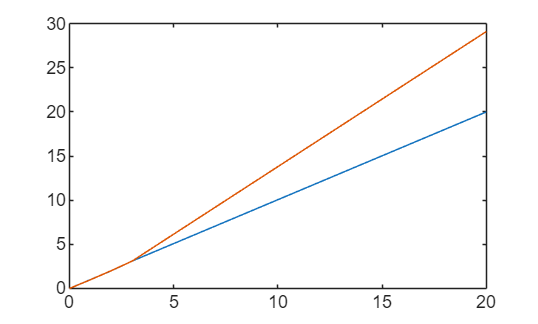



plot(xnoisy,ynoisy)

hold on

plot(xnoisy,fit2)

hold off

## Short theoretical background

Evaluate the goodness of fit using the R squared

The R squared is the following coefficient 


$$R^2 = 1-\frac{\sum_i( y_i-p_i)^2}{\sum_i(y_i-\mu)^2}$$
    

with

$y_i$ measured values

$p_i$ predicted values

$\mu$ mean of measured value

such that in the fraction in the numerator one finds the *error in estimates* and at the denominator the *variability in measured data*.

The R squared ranges from 0 (if the numerator is equal to the denominator) to 1 ( if predicted values equal the measured ones) 